clc
close all

f = logspace(1.699,5,10000);s=2*pi*f*1i;
R1=1e3;C1=100*1e-9;
R2=60;C2=68*1e-9;L2=4.7*1e-3;

f0_RC = 1/(2*pi*R1*C1)

f0_RC = 1.5915e+03

f0_RLC = 1/(2*pi*sqrt(L2*C2))

f0_RLC = 8.9026e+03


H_RC = 1./(1+1i*R1*C1.*s);
H_RLC = 1./(1-L2*C2.*s.^2+1i*R2*C2.*s);

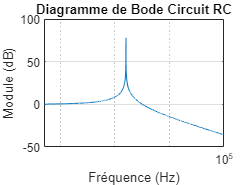

figure
semilogx(f,20*log10(abs(subs(H_RC))));
title('Diagramme de Bode Circuit RC')
xlabel('Fréquence (Hz)')
ylabel('Module (dB)')
xlim('tight')
grid on

[H_RCmax,m]=max(H_RC);
F0_RC = f(m)

F0_RC = 1.5913e+03

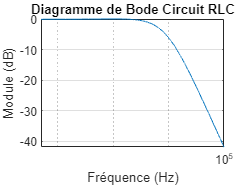


figure
semilogx(f,20*log10(abs(subs(H_RLC))));
title('Diagramme de Bode Circuit RLC')
xlabel('Fréquence (Hz)')
ylabel('Module (dB)')
xlim('tight')
grid on

[H_RLCmax,m]=max(H_RLC);
F0_RLC = f(m)

F0_RLC = 1.0162e+03

Unrecognized function or variable 'signal1'.